# **	Vision Artificial. GIEC.**

# **	Sistemas de Vision Artificial. GIC.**

**	Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá.**

**Nombre: Franck Michael Fierro Chicaiza**

**Fecha: 20/11/2023**

# Tema 4. Ejercicio 3 - Transformada de Fourier

El objetivo de la práctica es calcular la transformada de Fourier de todos los objetos de una imagen y utilizar sólo las componentes más significativas de cada objeto para reconstruirlos.

Step 1) Read Image

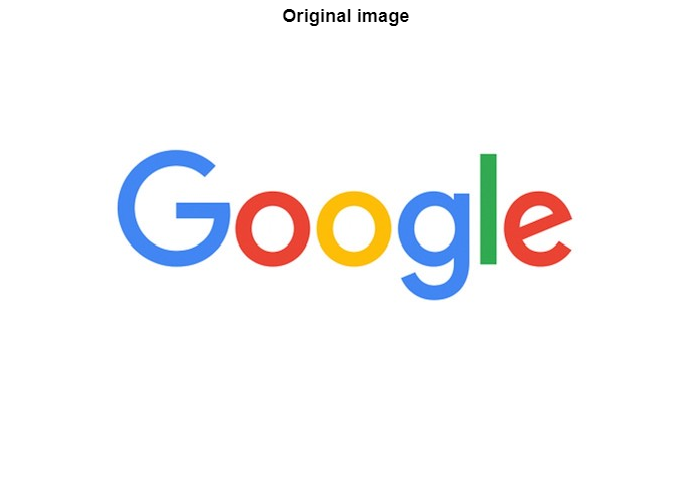

close all
clear all

imgOriginal = imread('./Imagenes/google.jpg');
figure;
imshow(imgOriginal);
title('Original image');

Step 2) Threshold the Image

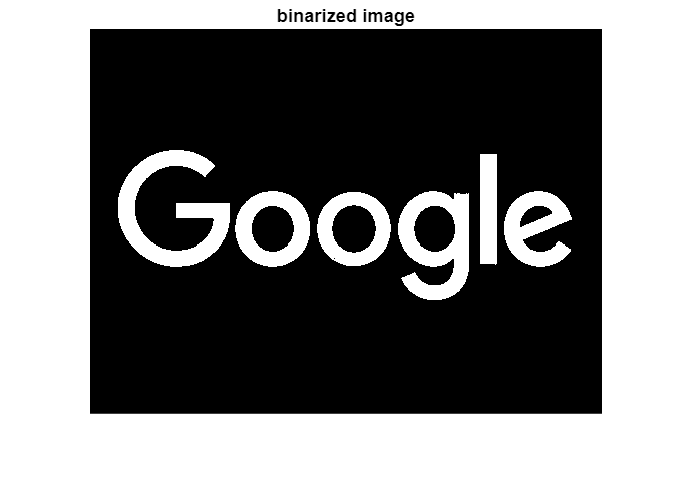

if size(imgOriginal,3) == 3
    imgOriginal = rgb2gray(imgOriginal); 
end
imgBW = imbinarize(imgOriginal);
imgBW = imcomplement(imgBW);

figure;
imshow(imgBW);
title('binarized image');

Step 4) Find the external Boundaries

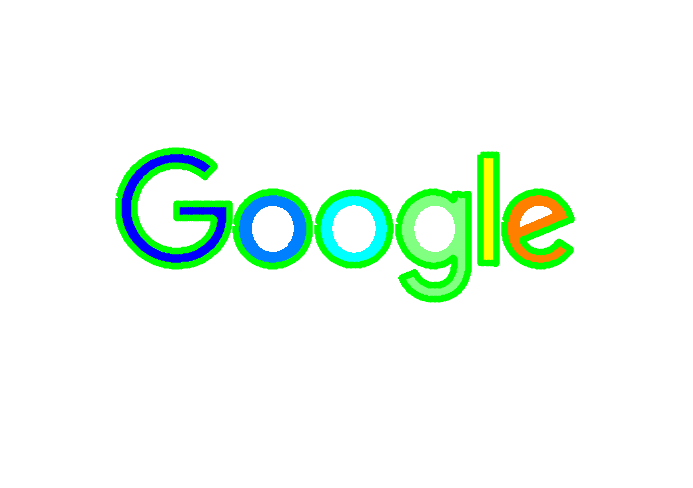

[B,L] = bwboundaries(imgBW,'noholes');
figure
imshow(label2rgb(L, @jet, [1.0 1.0 1.0]))
hold on
for k = 1:length(B)
    boundary = B{k};
    plot(boundary(:,2), boundary(:,1), 'g', 'LineWidth', 4);
end  

Step 5)  Fourier transform 

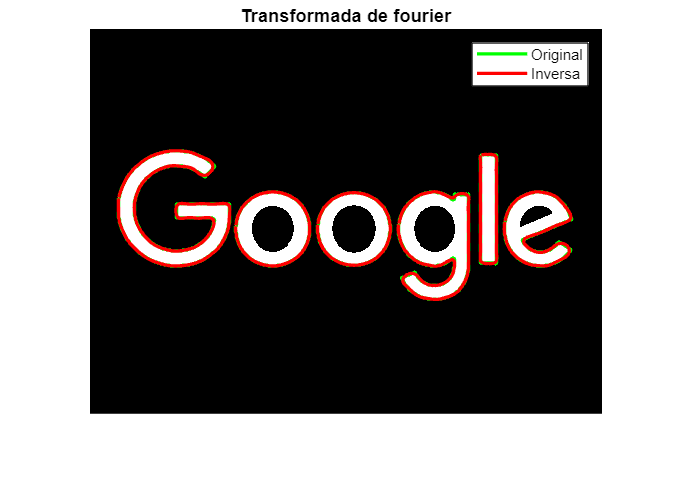

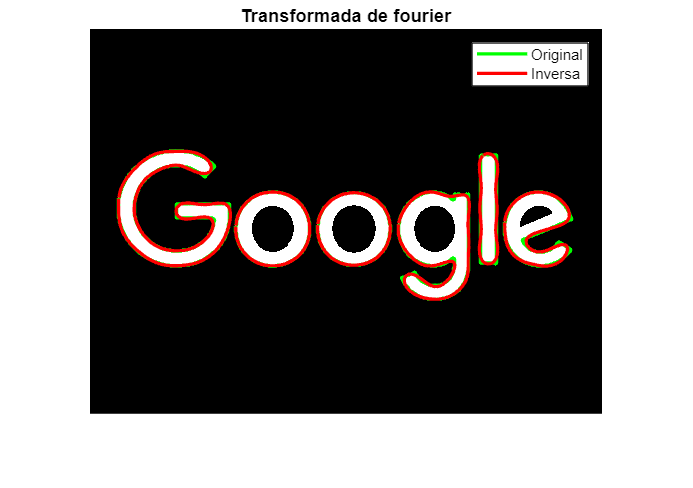

% Para el 10% de los datos
% Para el 2% de los datos
obtener_transformada(imgBW, B, 0.1);

Se pide: 

- Complete el paso 5, utilizando la función `fourier_transform(),` proporcionada con este enunciado, para obtener la transformada de Fourier de cada uno de los objetos etiquetados.

- Obtenga los contornos reconstruidos de los objetos etiquetados realizando la transformada inversa de Fourier con la función **fourier_inv_transform()**, también incluida con el enunciado. Visualice los comentarios de la función para realizar la reconstrucción utilizando solamente el 10% de las componentes. Dibuje el contorno recuperado. 

- Reduzca el número de componentes utilizados para la reconstrucción a 5% y 2% y explique sus conclusiones.

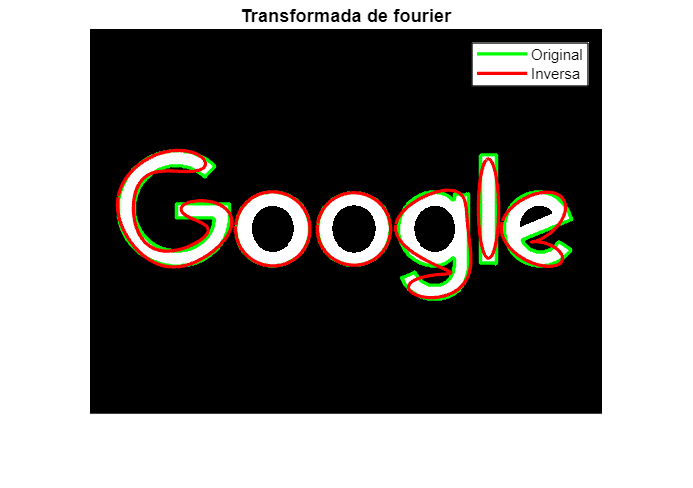

% Para el 5% de los datos
obtener_transformada(imgBW, B, 0.05);

% Para el 2% de los datos
obtener_transformada(imgBW, B, 0.02);

% Funcion para obtener la transforma de fourier

function obtener_transformada(imagen, bordes, porcentaje)
    figure,
    imshow(imagen);
    hold on;
    title('Transformada de fourier');
    
    for k = 1:length(bordes)
        boundary = bordes{k};
        
        % Transformada de fourier
        fft = fourier_transform(boundary);
        
        % Numero de componentes
        nc = length(fft) * porcentaje;
        % Transformada inversa de fourier
        fft_inv = fourier_inv_transform(fft, nc);
    
        % plot recovered boundary
        plot(boundary(:,2), boundary(:,1), 'g', 'LineWidth', 2);
        plot(fft_inv(:, 2), fft_inv(:, 1), 'r', 'LineWidth', 2);
        legend('Original', 'Inversa');
        
    end 
end


**Comentarios:**

- Podemos observar que al reducir el número de componentes en la reconstrucción, perdemos detalles en el borde de la imagen. Muchas de las esquinas se suavizan y adoptan formas de arcos de circunferencia. Aunque esta reducción de componentes conlleva un menor costo computacional, es evidente que se produce una pérdida en la fidelidad de la imagen. Por lo tanto, resulta crucial encontrar un equilibrio entre la calidad visual de la imagen (legibilidad y significado) y la carga computacional. La elección de un número óptimo de componentes se convierte en un aspecto importante para lograr un rendimiento eficiente y una representación visual adecuada.